# Estudo de Caso - critérios de qualidade

## 1. Utilizando o método da aula passada de coleta de dados, determine a funcao de transferencia do motor escolhido -  $G_{\textrm{motor}} \left(s\right)=\frac{Y\left(s\right)}{R\left(s\right)}=\frac{{\textrm{Velocidade}}_{\textrm{real}} }{{\textrm{Velocidade}}_{\textrm{desejada}} }$.

% Definir a função de transferência do motor
Gmotor = tf(1, [1 0.5 0])

Gmotor =
 
       1
  -----------
  s^2 + 0.5 s
 
Continuous-time transfer function.
Model Properties


Gc = tf(1, [1 0.5 0])

Gc =
 
       1
  -----------
  s^2 + 0.5 s
 
Continuous-time transfer function.
Model Properties


## 2. Determine teoricamente o ganho $K_x$do controlador do sistema ilustrado na Figura 1 que deixa o sistema proximo da oscilação. Para esta determinação utilize o comando `rlocus `para uso do lugar das raizes.

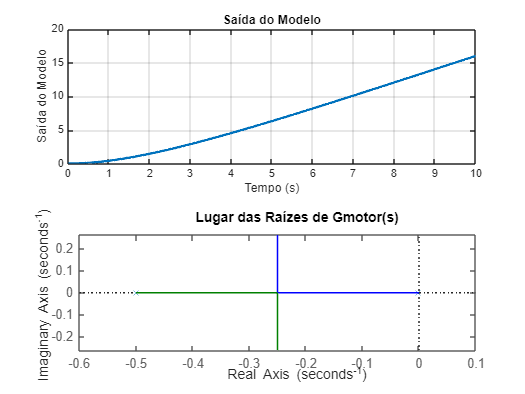

% Exibir o lugar das raízes para determinar o ganho Kx
rlocus(Gmotor);
title('Lugar das Raízes de Gmotor(s)');

s = -0.25; % tirado do gráfico
Kx = -1 / evalfr(Gc, s) * evalfr(Gmotor, s)

Kx = -1

## 3. Implemente o diagrama no ambiente ***Simulink*** e faça a validação da resposta prevista e da resposta real.

##  A correta medida da frequencia de oscilação - `ωx` e parametro importante de validação

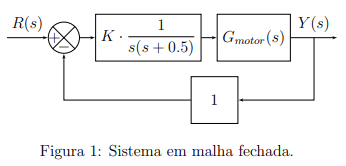

## 4. O que acontece se utilizarmos o ganho $K>K_x$? como voce avalia o resultado e justifica interpretando a resposta temporal com os polos calculados.

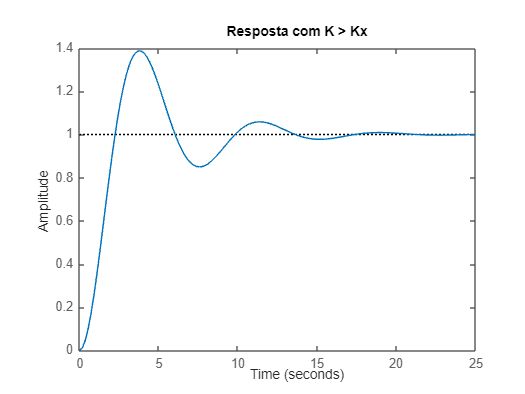

K = Kx + 1;  % Ganho maior que Kx
closed_loop_system = feedback(K * Gmotor, 1);
figure;
step(closed_loop_system);
title('Resposta com K > Kx');

## 5. O que acontece se utilizarmos o ganho $K<K_x$? como voce avalia o resultado e justifica interpretando a resposta temporal com os polos calculados.

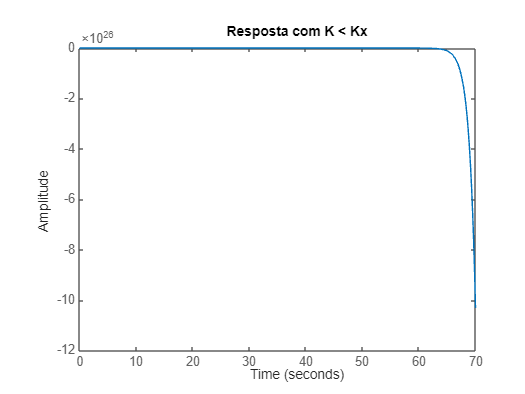

K = Kx - 1;  % Ganho menor que Kx
closed_loop_system = feedback(K * Gmotor, 1);
figure;
step(closed_loop_system);
title('Resposta com K < Kx');

## 6. Plotagem dos resultados

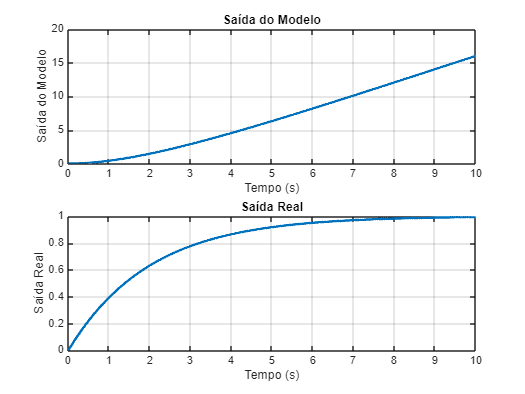

% Obter respostas temporais
tempo = 0:0.01:10;  % Vetor de tempo
entrada = ones(size(tempo));  % Sinal de entrada (degrau unitário)
ym = lsim(Gmotor, entrada, tempo);  % Resposta do modelo

% Plotar resposta do modelo e resposta real (exemplo)
figure;
subplot(2, 1, 1);  % Saída do modelo
plot(tempo, ym, 'linewidth', 2);
xlabel('Tempo (s)');
ylabel('Saída do Modelo');
title('Saída do Modelo');
grid on;

% Simulação da resposta real (hipotética para o exemplo)
velocidade_real = 1 - exp(-0.5*tempo);  % Resposta real (ajustar conforme dados reais)
subplot(2, 1, 2);  % Saída real
plot(tempo, velocidade_real, 'linewidth', 2);
xlabel('Tempo (s)');
ylabel('Saída Real');
title('Saída Real');
grid on;